# Binary Image Processing

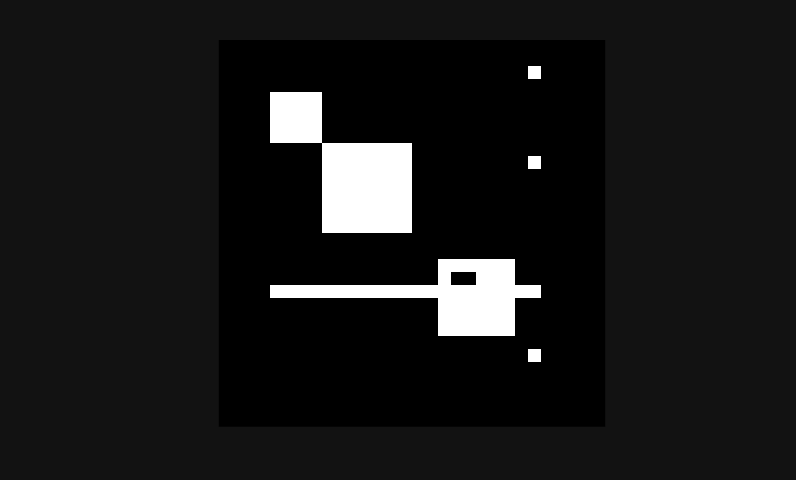

img = false(30, 30);
img(5:8, 5:8) = true;
img(9:15, 9:15) = true;
img(18:23, 18:23) = true;
img(19:20, 19:20) = false;
img(5:8, 5:8) = true;
img(20, 5:25) = true;
img(3, 25) = true;
img(10, 25) = true;
img(25, 25) = true;
imshow(img)

## STREL

getnhood(strel("square", 3))

ans = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


getnhood(strel("rectangle", [3 5]))

ans = 3×5 logical array
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1


getnhood(strel("diamond", 2))

ans = 5×5 logical array
   0   0   1   0   0
   0   1   1   1   0
   1   1   1   1   1
   0   1   1   1   0
   0   0   1   0   0


getnhood(strel("disk", 2))

ans = 5×5 logical array
   0   0   1   0   0
   0   1   1   1   0
   1   1   1   1   1
   0   1   1   1   0
   0   0   1   0   0


getnhood(strel("octagon", 3))

ans = 7×7 logical array
   0   0   1   1   1   0   0
   0   1   1   1   1   1   0
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   0   1   1   1   1   1   0
   0   0   1   1   1   0   0


getnhood(strel("line", 5, 4))

ans = 1×5 logical array
   1   1   1   1   1



se = strel("square", 3);
decompose(se)

ans = strel is a square shaped structuring element with properties:

      Neighborhood: [3×3 logical]
    Dimensionality: 2


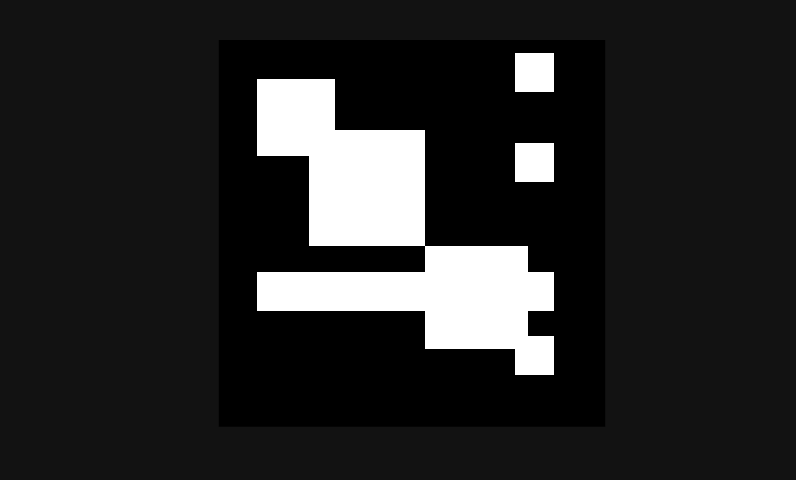


dil = imdilate(img, se); imshow(dil)

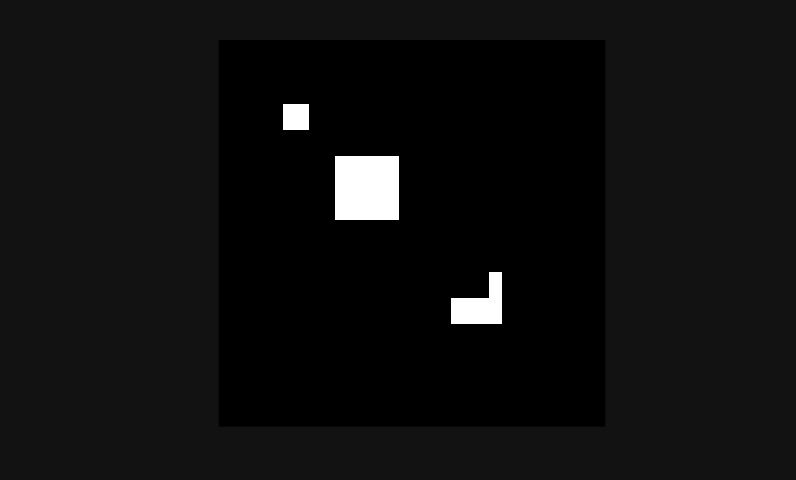

erod = imerode(img,se); imshow(erod)

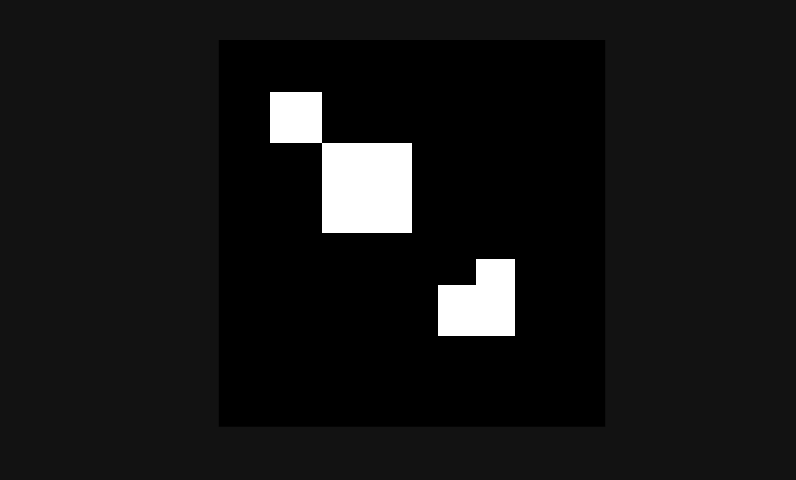

open = imopen(img,se); imshow(open) % remove small white patches

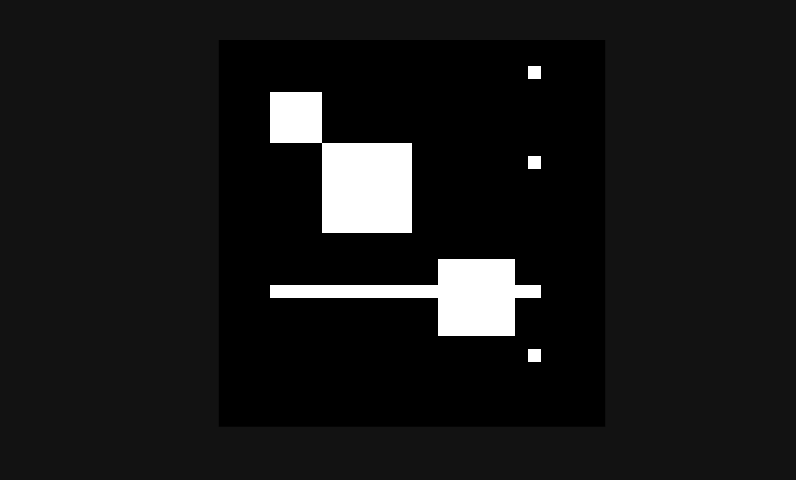

close = imclose(img,se); imshow(close) % close small black patches

## EDGE DETECTION

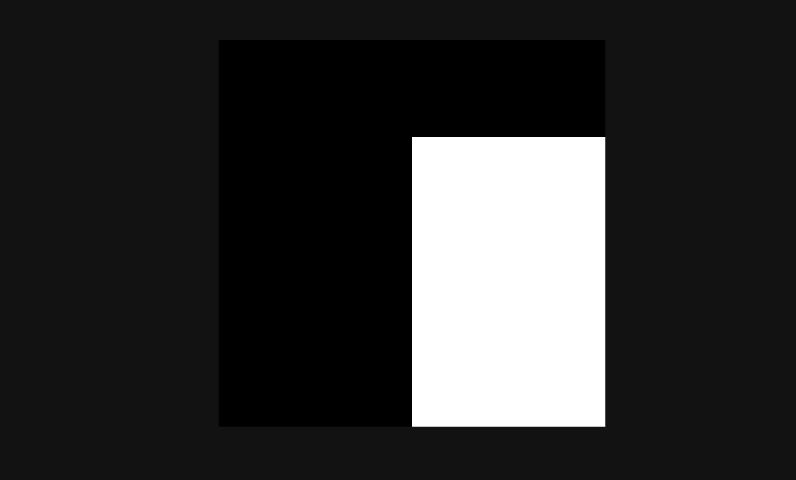

% break_down
I = [10 10 10 10; 10 10 80 80; 10 10 80 80; 10 10 80 80];
imshow(I, [])

Gx = [1 0; 0 -1];
Gy = [0 1; -1 0];

gx = filter2(Gx, I, 'valid')  

gx =      0   -70   -70
     0   -70     0
     0   -70     0


gy = filter2(Gy, I, 'valid')

gy =      0     0   -70
     0    70     0
     0    70     0


G  = sqrt(gx.^2 + gy.^2)

G =          0   70.0000   98.9949
         0   98.9949         0
         0   98.9949         0


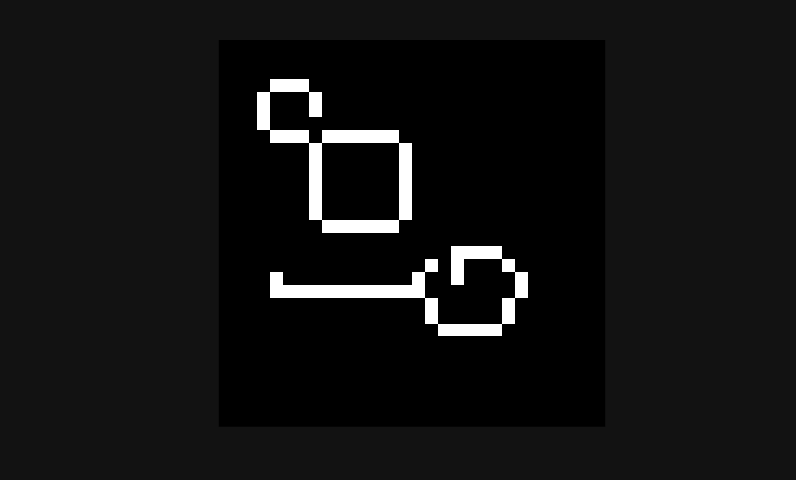


% roberts (focuses on cross gradients)
BW = edge(img, 'roberts');
imshow(BW)

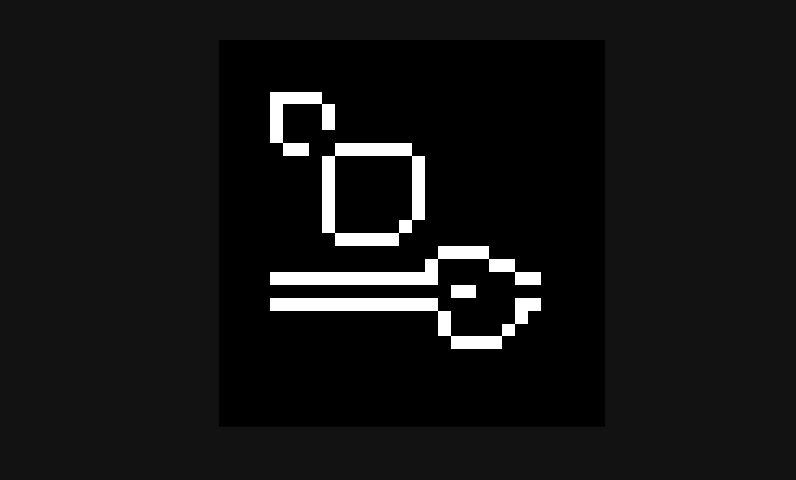


% sobel (vertical and horizantal edges)
BW = edge(img, 'sobel');
imshow(BW)

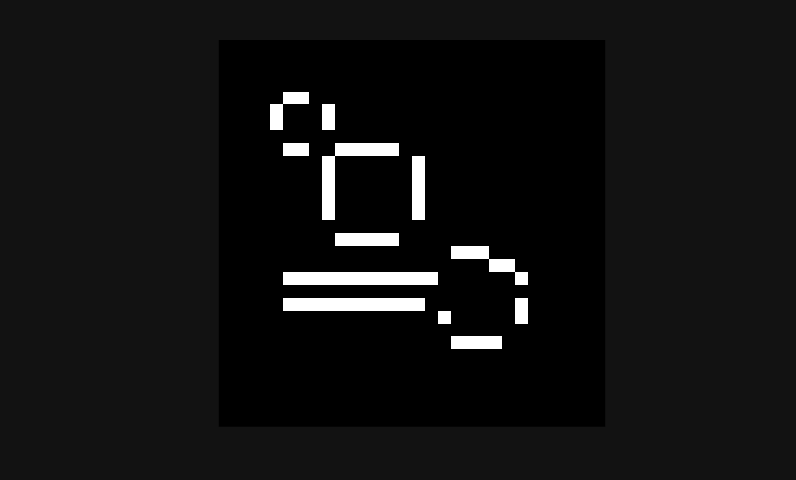


% prewitt (similar to sobel)
BW = edge(img, 'prewitt');
imshow(BW)

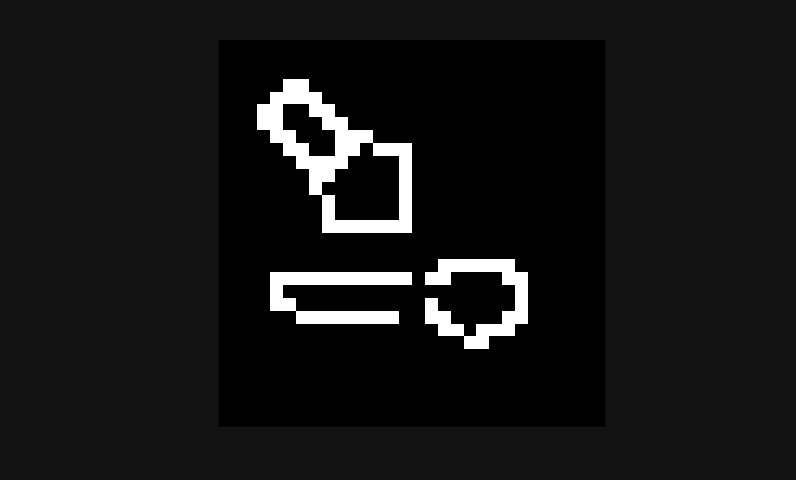


% canny
%% smooth >> sobel >> hysteresis
% weak edge kept if it connects strong edge
BW = edge(img, 'canny');
imshow(BW)

## HIT AND MISS

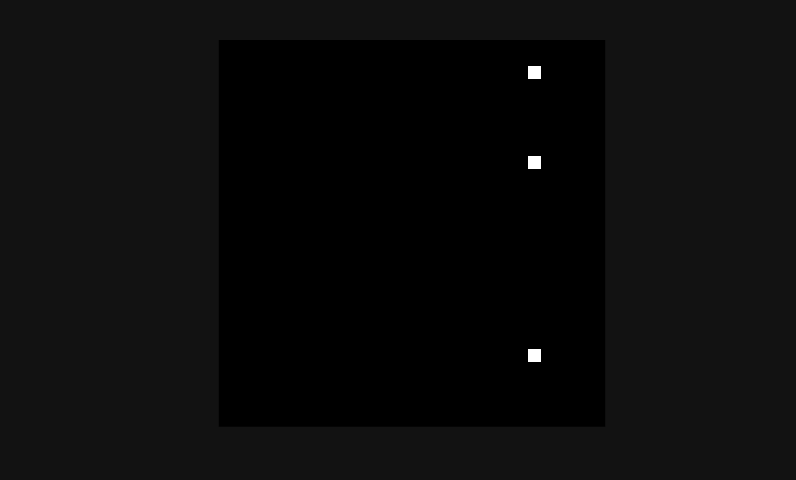

SE1 = [0 0 0; 0 1 0; 0 0 0];
SE2 = [1 1 1; 1 0 1; 1 1 1];
iso = bwhitmiss(img, SE1, SE2);
imshow(iso)

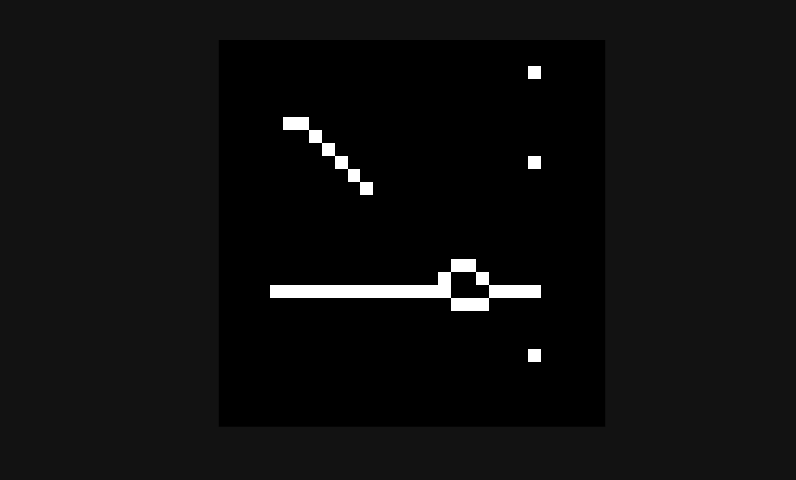


thin = bwmorph(img, 'thin', Inf); imshow(thin)   

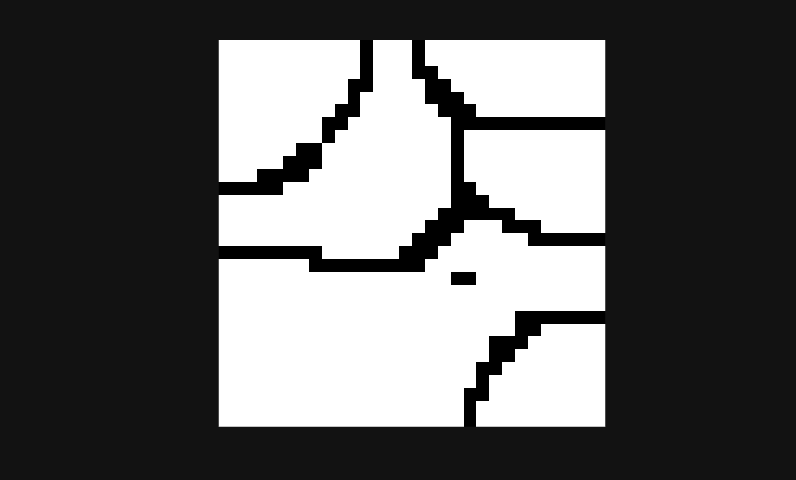

thick = bwmorph(img, 'thick', Inf); imshow(thick)

## EXAMPLE

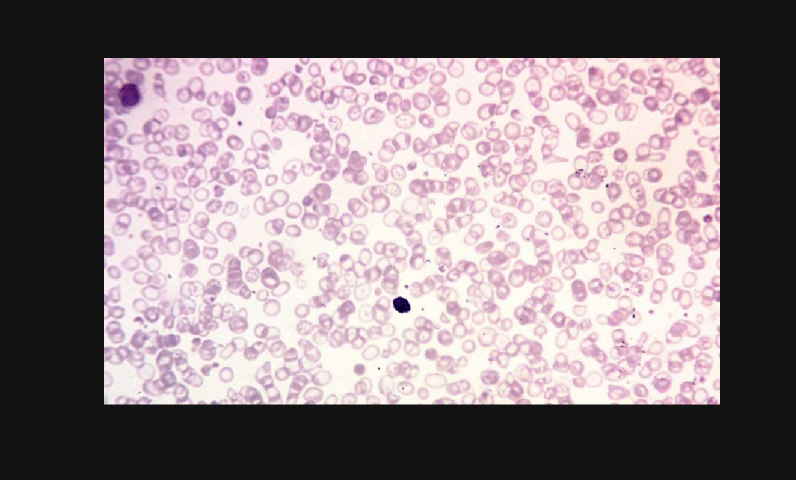

im = imread("images/rbc.jpg"); imshow(im)

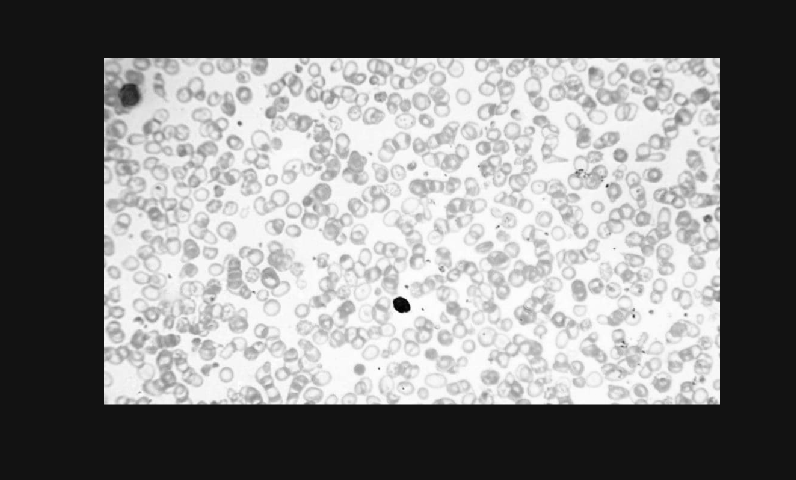

gray = rgb2gray(im); imshow(gray,[])

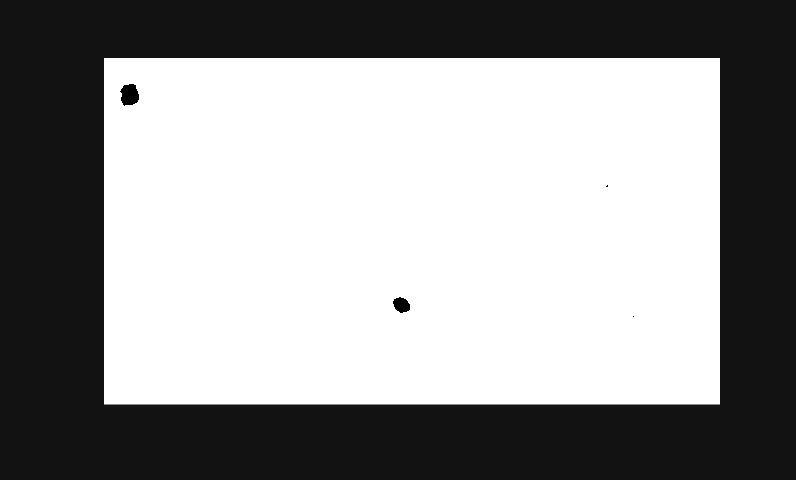

bw = imbinarize(gray, 0.3); imshow(bw)